What we do here is we calculate achieavable rates for the BS versus  No. users.

clc
close all

% parameters
N1 = 3 ;                           % No.  users
N_i = 15 ;                         % No.  IRS elements
N_iter = 2 ;                     % No. iteraions
P_T = (10^(40/10)) * 1e-3 ;               % BS power(w)
R = 10 ;                           % Radius
[x0,y0,z0] = deal(30,20,0) ;         % user area center
[x1,y1,z1] = deal(0,0,10) ;       % BS1 location
[x_i,y_i,z_i] = deal(25 * sqrt(2),25 * sqrt(2),10) ;   % IRS location
M_t = 1 ;                          % No. of transmitter antennas
M_r = 1 ;                          % No. of receiver antennas
alpha_d = 3.6 ;
alpha_r = 2 ;
noise_power = (10^(-114/10)) ;     % -169dbm/Hz
interference = 0 ;
epsilon = 0.01 ;
SV = 5 ;


%% Calculate the rates
channel_gain = zeros(N1,1) ;
start = 5 ;
step = 1 ;
final_Lband = zeros(SV,1) ;
final_rate = zeros(SV,1) ;
random_final_rate = zeros(SV,1) ;
tic
N = N_i ;
m = repmat('.', 1, SV) ;
for N1 = start : step : (SV - 1) * step + start
    m(floor((N1 - start)/ step) + 1) = '|' ;
    disp(m)
    i = 1+floor((N1 - start)/step) ; 
    %% users location
    t = 2 * pi * rand(N1,1) ;
    r  =  R * sqrt(rand(N1,1)) ;
    x  =  x0 + r.* cos(t) ;
    y  =  y0 + r.* sin(t) ;
    z = 1.5 * ones(N1,1) ;
    for k = 1 : N_iter
        %% channel gains
        h_d = (10^0.2) * (randn(N1,M_t,M_r) + 1j * randn(N1,M_t,M_r)) * sqrt(1/2).* ((10^0.2)./(sqrt( (x-x1).^2 + (y-y1).^2 + (z-z1).^2 )).^alpha_d) ;
        g = (10^0.2) * (randn(N,M_t,M_r) + 1j * randn(N,M_t,M_r)) * sqrt(1/2).* ((10^0.2)./(sqrt( (x_i-x1).^2 + (y_i-y1).^2 + (z_i-z1).^2 )).^alpha_r) ;
        h_r = zeros(N,N1) ;
        for j = 1 : N1
            h_r( : ,j) = (10^0.2) * (randn(N,M_t,M_r) + 1j * randn(N,M_t,M_r)) * sqrt(1/2).* ((10^0.2)./(sqrt( (x(j)-x_i).^2 + (y(j)-y_i).^2 + (z(j)-z_i).^2 )).^alpha_r) ;
        end
        [~, Z_cvx] = Rate2(h_d, g, h_r, N1, N, P_T, noise_power, N_iter) ;
        Theta = diag(Z_cvx) ;
        channel_gain = sort(abs(h_d + h_r'  *  Theta  *  g)) ;
        [exact_rate, ~] = SISONoma(epsilon, channel_gain.^2  *  P_T / noise_power) ;
        final_rate(i) = final_rate(i) +  exact_rate ;
        rate_lower_bound = log2(1 + P_T * channel_gain(1)^2/noise_power)/N1 ;
        final_Lband(i) = final_Lband(i) +  rate_lower_bound ;
        %% random theta
        rand_theta = exp(1j * 2 * pi * rand(N,1))  ;
        channel_gain = abs(h_d + h_r' * diag(rand_theta) * g)  ;
        channel_gain = sort(abs(channel_gain))  ;
        rate_lower_bound = log2(1 + P_T * channel_gain(1)^2/noise_power)/N1 ;
        random_final_rate(i) = random_final_rate(i) + rate_lower_bound ;
    
    end
end

|....
||...
|||..
||||.
|||||


final_rate = (final_rate.*(start : step : (SV - 1) * step + start)')/N_iter ;
final_Lband = final_Lband.*(start : step : (SV - 1) * step + start)'/N_iter ;
random_final_rate = random_final_rate.*(start : step : (SV - 1) * step + start)'/N_iter ;
toc

Elapsed time is 51.628629 seconds.


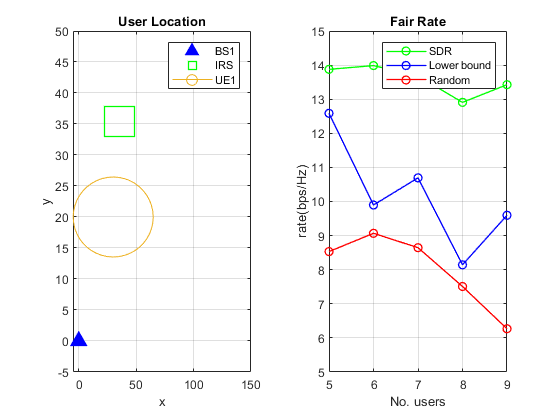


%% plot 1 SumRate
figure
tiledlayout(1,2)
nexttile
%  draw BS1
set(gca,'FontName','Times New Roman','FontSize',11,'LineWidth',1.5)  ; 
plot(0,0,'^','MarkerSize',10,...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor','b','linewidth',1)
hold on
% draw IRS
plot(x_i,y_i,'gs','MarkerSize',30,'linewidth',1)
% draw BS1 users
plot(x0,y0,'o-','MarkerSize',60  *  R/10,'linewidth',0.1)
% configs
title('User Location')
xlabel('x')
ylabel('y')
xlim([-5 150])  ; 
ylim([-5 50])  ; 
legend('BS1','IRS','UE1')  ; 
grid on
nexttile
% draw results
plot(start : step : start + (SV - 1 ) * step,final_rate, 'g-o','linewidth',1)
hold on
plot(start : step : start + (SV - 1 ) * step,final_Lband, 'b-o','linewidth',1)
plot(start : step : start + (SV - 1 ) * step,random_final_rate, 'r-o','linewidth',1)
set(gcf,'color','w');
ylim([5 15 ])
title('Fair Rate')
xlabel('No. users')
ylabel('rate(bps/Hz)')
legend('SDR', 'Lower bound','Random')
grid on

%% Save the figure
saveas(gcf,['rate for ', num2str(N_iter),' Iterations and ', num2str(N1),' users.epsc'])
